## Load data

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\Figures\Figure5DiurnalPlot'
cd data\input\
load('BflatEdCov.mat')
load('Bflat30min.mat')
load('BLM93C.mat')

### FED stage relationship to evaporation rate

bflatEdCov.timeMDT = datenum(timeofday(bflatEdCov.Date_Time_MDT));
bflatEdCov = timetable2table(bflatEdCov);
bflatEdCov = bflatEdCov(:,[2:end]);
Flooding = bflatEdCov([22:195,229:500],:);
Desiccation = bflatEdCov([643:1623,1665:1841,2159:end],:);
Desiccation.albedo = Desiccation.OutRad_sw_Wm2./Desiccation.SolarRad_Wm2;

FloodingDiurnal = grpstats(Flooding, 'timeMDT', 'mean');
FloodingDiurnalStd = grpstats(Flooding, 'timeMDT', "std");
DesiccationDiurnalStudyPeriod = grpstats(Desiccation, 'timeMDT', 'mean');
DesiccationDiurnalStudyPeriodMedian = grpstats(Desiccation, 'timeMDT', 'median');

### Desiccation Stage Diurnal Evaporation

load('BflatEdCov.mat')
Desiccation = bflatEdCov([643:1623,1665:1841,2159:end],:);

#### Median values

[Desiccation] = grpStatsTime(Desiccation,'timeMDT', 'median');
Desiccation.smoothedData = smoothdata(Desiccation.median_Evaporation_mm30min,...
    'loess','SmoothingFactor',0.70,'SamplePoints',Desiccation.timeMDT);

#### Standard Deviation Values

DesiccationStdStudyPeriod = bflatEdCov([643:1623,1665:1841,2159:end],:);
[DesiccationStdStudyPeriod] = grpStatsTime(DesiccationStdStudyPeriod, 'timeMDT', 'std');

#### Smooth evaporation data

% DesiccationDiurnalStudyPeriod.mean_Evaporation_mm30min*24 + DesiccationStdStudyPeriod.std_Evaporation_mm30min*24

FloodingDiurnalStd.std_Evaporation_mm30min = smoothdata(FloodingDiurnalStd.std_Evaporation_mm30min,...
    'movmedian','SmoothingFactor',0.35);
DesiccationStdStudyPeriod.std_Evaporation_mm30min = smoothdata(DesiccationStdStudyPeriod.std_Evaporation_mm30min,...
    'movmedian','SmoothingFactor',0.45);
DesiccationDiurnalStudyPeriod.mean_Evaporation_mm30min = smoothdata(DesiccationDiurnalStudyPeriod.mean_Evaporation_mm30min,...
    'gaussian','SmoothingFactor',0.52);

## Load all BFLAT data, pare to July

well = Bflat30min;
well = retime(well, "hourly","mean");
well.month = month(well.Date_Time_MDT);
well.timeMDT = datenum(timeofday(well.Date_Time_MDT));
well.monthhour = well.month + well.timeMDT;
well = well(well.month == 7, :); %Pare to July
well = well(754:end,:); %Remove July 2017 (poor radiation data). Dataset is now July 2018-July 2021

Desiccation = well;

Desiccation.albedo = Desiccation.OutRad_sw_Wm2./Desiccation.SolarRad_Wm2;
[DesiccationStd] = grpStatsTime(Desiccation, 'timeMDT', 'std');
[DesiccationDiurnal] = grpStatsTime(Desiccation, 'timeMDT', 'mean');

%Set albedo values
DesiccationDiurnal.mean_albedo(1:7) = NaN;
DesiccationDiurnal.mean_albedo(21:24) = NaN;
DesiccationStd.std_albedo(1:7) = NaN;
DesiccationStd.std_albedo(21:24) = NaN;

#### Analyze/Group water level data

BLM93C = removevars(BLM93C, 'WellID_BLM');
BLM93C = retime(BLM93C, 'hourly',"mean");
well = BLM93C;
well.month = month(well.Date_Time_MDT);
well.timeMDT = datenum(timeofday(well.Date_Time_MDT));
well.monthhour = well.month + well.timeMDT;

well = well(well.month == 7, :); %Select only July for diurnal water level data

[JulyBLM93Cstd] = grpStatsTime(well,'monthhour', 'std'); %chagne to BLM93Cstd
[JulyBLM93C] = grpStatsTime(well,'monthhour', 'mean');


## Modeled water level change from temp

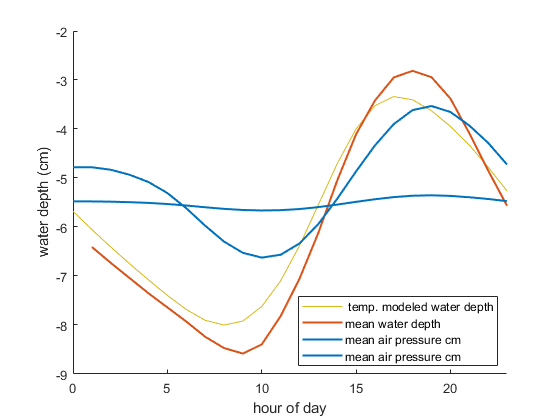

DesiccationDiurnal.mean_SoilTemp_C_gradient = gradient(DesiccationDiurnal.mean_SoilTemp_C); %change in soil temp
DesiccationDiurnal.dWDdST = (DesiccationDiurnal.mean_SoilTemp_C_gradient)*0.76; %summer scaling factor - temp change to water level change
DesiccationDiurnal.dWaterDepthPerT = cumsum(DesiccationDiurnal.dWDdST, 'omitnan') -5.3; %shift down

figure
hold on 
plot(DesiccationDiurnal.timeMDT*24,DesiccationDiurnal.dWaterDepthPerT,'color', [0.8500 0.7250 0.0980],'DisplayName',' temp. modeled water depth')
plot(JulyBLM93C.mean_WaterLevelBelowSurface_m*-100,'linewidth', 1.5, 'DisplayName','mean water depth')
plot(DesiccationDiurnal.timeMDT*24, -DesiccationDiurnal.mean_Pressure_kPa*10.1972/1.2 +736, 'linewidth', 1.5,  ...
     'color',[0 0.4470 0.7410], 'displayname', 'mean air pressure cm') %adjusted for density - inverted for effect and shifted.
plot(DesiccationDiurnal.timeMDT*24, (-DesiccationDiurnal.mean_Pressure_kPa*10.1972/1.2 +736)*0.1-5, 'linewidth', 1.5,  ...
     'color',[0 0.4470 0.7410], 'displayname', 'mean air pressure cm') %adjusted for density - inverted for effect and shifted. Now shown assuming 0.9 barometric efficiency

legend("Location","best")
xlim([0,23])
xlabel('hour of day')
ylabel('water depth (cm)')

%Temporal lag in heating, small possible impact of air pressure
%contriubting to offset - the peak pre-dates air-pressure inidicating air
%pressure was not the driving factor. Air pressure scaled for 0.9
%barometric efficiency would lead to very small change. 

## FIGURE - Diurnal processes when surface dessicated

figure
tiledlayout (7, 2)

#### Evaporation during flooding stage

nexttile 
FloodingDiurnal.mean_Evaporation_mm30minSmoothed = smoothdata(FloodingDiurnal.mean_Evaporation_mm30min,...
    'loess','SmoothingFactor',0.09999999999999998);
hold on 
plot(FloodingDiurnal.timeMDT*24, FloodingDiurnal.mean_Evaporation_mm30minSmoothed*24*2, 'linewidth', 1.5,'color',[0 0.4470 0.7410],  ...
    'displayname', 'mean')
plot(FloodingDiurnal.timeMDT*24, FloodingDiurnal.mean_Evaporation_mm30minSmoothed*24*2 - FloodingDiurnalStd.std_Evaporation_mm30min*24*2,':', 'linewidth', 0.5,  ...
    'color',[0 0.4470 0.7410],'displayname', 'std. dev.')
plot(FloodingDiurnal.timeMDT*24, FloodingDiurnal.mean_Evaporation_mm30minSmoothed*24*2 + FloodingDiurnalStd.std_Evaporation_mm30min*24*2,':', 'linewidth', 0.5,  ...
    'color',[0 0.4470 0.7410],'displayname', 'std. dev.', 'HandleVisibility',"off")

legend('location',"eastoutside")
ylabel('flooding E_a (mm d^-^1)')
xlim([0,23])
ylim([0,1.7*2])
xticks([0:23])
xticklabels('')

#### Evaporation data Dessication Stage

nexttile 
nexttile ([1,1])
hold on
sz = 10;
scatter(DesiccationDiurnalStudyPeriod.timeMDT*24, DesiccationDiurnalStudyPeriodMedian.median_Evaporation_mm30min*24*2, sz,  ...
    [0 0.4470 0.7410], 'displayname', 'median')
plot(DesiccationDiurnalStudyPeriod.timeMDT*24, DesiccationDiurnalStudyPeriod.mean_Evaporation_mm30min*24*2, 'linewidth', 1.5,  ...
    'color',[0 0.4470 0.7410],'displayname', 'mean')
plot(DesiccationDiurnalStudyPeriod.timeMDT*24, DesiccationDiurnalStudyPeriod.mean_Evaporation_mm30min*24*2 + DesiccationStdStudyPeriod.std_Evaporation_mm30min*24*2,":", 'linewidth', 0.5, ...
    'color',[0 0.4470 0.7410], 'displayname', 'std. dev.')
plot(DesiccationDiurnalStudyPeriod.timeMDT*24, DesiccationDiurnalStudyPeriod.mean_Evaporation_mm30min*24*2 - DesiccationStdStudyPeriod.std_Evaporation_mm30min*24*2,":", 'linewidth', 0.5,  ...
    'color',[0 0.4470 0.7410], 'displayname', 'std. dev.', 'HandleVisibility',"off")
ylabel('desiccation E_a (mm d^-^1)')

ylim([-0.02,0.1])
xlim([0,23])
xticks([0:23])
xticklabels('')
legend('location',"eastoutside")

#### Wind

nexttile 
nexttile 
hold on
DesiccationDiurnal.mean_WindSpeed_kph = smoothdata(DesiccationDiurnal.mean_WindSpeed_kph,...
    'loess','SmoothingFactor',0.25,'SamplePoints',DesiccationDiurnal.timeMDT);
plot(DesiccationDiurnal.timeMDT*24, DesiccationDiurnal.mean_WindSpeed_kph*0.277778,'linewidth', 1.5,  ...
    'displayname', 'mean wind') %Multiply by 0.277778 to convert to m/s
hold on
plot(DesiccationDiurnal.timeMDT*24, (DesiccationDiurnal.mean_WindSpeed_kph- DesiccationStd.std_WindSpeed_kph)*0.277778, ':','linewidth', 0.5,  ...
    'color',[0 0.4470 0.7410], 'displayname', 'wind std. dev.')
plot(DesiccationDiurnal.timeMDT*24, (DesiccationDiurnal.mean_WindSpeed_kph + DesiccationStd.std_WindSpeed_kph)*0.277778, ':','linewidth', 0.5,  ...
    'color',[0 0.4470 0.7410],'displayname', 'wind speed (kph)', 'HandleVisibility','off')
ylabel('wind speed (m s^-^1)')
% ylim([2,25])
xticklabels('')

#### Albedo

nexttile 
nexttile 

xlim([0,23])
xticks([0:23])
xticklabels('')

hold on
plot(DesiccationDiurnal.timeMDT*24, DesiccationDiurnal.mean_albedo,'linewidth', 1.5,  ...
    'displayname', 'mean albedo')
plot(DesiccationDiurnal.timeMDT*24, DesiccationDiurnal.mean_albedo - DesiccationStd.std_albedo,':', 'linewidth', 0.5,  ...
    'color',[0 0.4470 0.7410],'displayname', 'albedo std. dev.')
plot(DesiccationDiurnal.timeMDT*24, DesiccationDiurnal.mean_albedo + DesiccationStd.std_albedo,':', 'linewidth', 0.5,  ...
    'color',[0 0.4470 0.7410],'displayname', 'albedo', 'HandleVisibility','off')

% legend('location',"eastoutside")
ylabel('albedo')
ylim([0.38,0.46])
xticks([0:23])
xticklabels('')

#### Air pressure

% nexttile 
nexttile 
nexttile 

DesiccationDiurnal.mean_Pressure_kPa = smoothdata(DesiccationDiurnal.mean_Pressure_kPa,...
    'loess','SmoothingFactor',0.15,'SamplePoints',DesiccationDiurnal.timeMDT);
hold on 
plot(DesiccationDiurnal.timeMDT*24, DesiccationDiurnal.mean_Pressure_kPa*10.1972/1.2, 'linewidth', 1.5,  ...
     'color',[0 0.4470 0.7410], 'displayname', 'mean')
plot(DesiccationDiurnal.timeMDT*24, (DesiccationDiurnal.mean_Pressure_kPa - DesiccationStd.std_Pressure_kPa)*10.1972/1.2,':', 'linewidth', 0.5,  ...
     'color',[0 0.4470 0.7410], 'displayname', 'std. dev.')
plot(DesiccationDiurnal.timeMDT*24, (DesiccationDiurnal.mean_Pressure_kPa + DesiccationStd.std_Pressure_kPa)*10.1972/1.2, ':', 'linewidth', 0.5,  ...
     'color',[0 0.4470 0.7410], 'displayname', 'std. dev.', 'HandleVisibility','off')

legend('location',"eastoutside")
ylabel('air pres. (cm H_2O)')
xlim([0,23])
ylim([737,744.5])
xticks([0:23])
xticklabels('')

#### Soil temp

nexttile 
nexttile 
DesiccationDiurnal.mean_SoilTemp_C = smoothdata(DesiccationDiurnal.mean_SoilTemp_C,...
    'loess','SmoothingFactor',0.1,'SamplePoints',DesiccationDiurnal.timeMDT);
hold on 
plot(DesiccationDiurnal.timeMDT*24, DesiccationDiurnal.mean_SoilTemp_C,'linewidth', 1.5,  ...
    'color',[0 0.4470 0.7410],'displayname', 'mean ground temp.')
plot(DesiccationDiurnal.timeMDT*24, DesiccationDiurnal.mean_SoilTemp_C - DesiccationStd.std_SoilTemp_C,':','linewidth', 0.5,  ...
    'color',[0 0.4470 0.7410],'displayname', 'ground temp. std. dev.')
plot(DesiccationDiurnal.timeMDT*24, DesiccationDiurnal.mean_SoilTemp_C + DesiccationStd.std_SoilTemp_C,':','linewidth', 0.5,  ...
    'color',[0 0.4470 0.7410],'displayname', 'ground temp. 10 cm', 'HandleVisibility','off')

ylabel('ground temp. (^oC)')
xlim([0,23])
xticks([0:23])
xticklabels('')
% xlabel('hour','fontsize',10)
legend("Location",'eastoutside')

nexttile 

#### Measured and modeled water depth

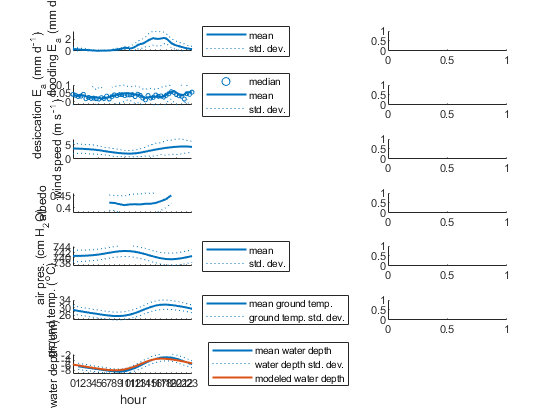

nexttile 
hold on
plot(JulyBLM93C.mean_WaterLevelBelowSurface_m*-100,'linewidth', 1.5, 'DisplayName','mean water depth')
hold on
plot(JulyBLM93C.mean_WaterLevelBelowSurface_m*-100 - JulyBLM93Cstd.std_WaterLevelBelowSurface_m*-100,':','linewidth', 0.5, ...
    'color',[0 0.4470 0.7410],'DisplayName','water depth std. dev.')
plot(JulyBLM93C.mean_WaterLevelBelowSurface_m*-100 + JulyBLM93Cstd.std_WaterLevelBelowSurface_m*-100,':','linewidth', 0.5, ...
    'color',[0 0.4470 0.7410],'DisplayName','water depth std. dev.', 'HandleVisibility','off')
plot(DesiccationDiurnal.timeMDT*24,DesiccationDiurnal.dWaterDepthPerT,'linewidth', 1.5,'color', [0.8500 0.3250 0.0980],'DisplayName','modeled water depth')
legend("Location",'eastoutside')
ylabel('water depth (cm)')
xlim([0,23])
ylim([-9.5,-1.5])
xticks([0:23])
xlabel('hour','fontsize',10)
cd ..\output\
% savefig("Diurnal Evap")
print('Diurnal Evap all BFLAT data', '-fillpage','-dpdf') 

function [well] = grpStatsTime(well, periodcolumn, grouping)
well = timetable2table(well);
well = well(:,[2:end]);
well = grpstats(well, periodcolumn, grouping);
end